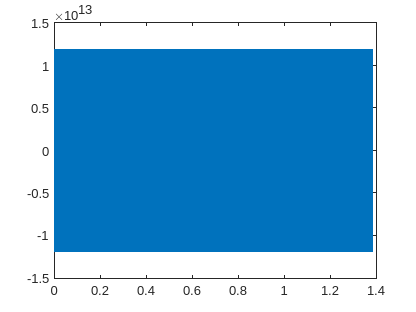

clc; clear all; close all;

% This is Hydraulic System number 10 . rho (density) = 875 kg/m^3 . beta (bulk modulus) = 1100 MPa . Minimum gauge pressure (vacuum) = -1 bar , ps01 = 140 bar , Cd1 = 0.75 , Ad1 = 37 mm^2 , Cd2 = 0.69 , Ad2 = 8 mm^2 , Cd3 = 0.59 , Ad3 = 34 mm^2 , tRU1 = 231 milliSeconds , d1 = 50 mm , dr1 = 25 mm , h01 = 1036 mm , m1 = 2414 kg , h1 = 777 mm , k1 = 212000 N/m , L01 = 518 mm , Linear damper b1 = 42000 N*s/m , p1 (initial value) = 0 bar , p2 (initial value) = 0 bar , x1 (initial value) = 259 mm , x1Dot (initial value) = 0 mm/s , simulation time = 1386 milliSeconds . What is the maximum absolute value of the flow in orifice 1 [l/min] ?

rho = 875; % kg/m^3
beta = 1100*10^6; % Pa
gauge_min = -1*10^5; % Pa

ps01 = 140*10^5; % Pa

Cd1 = 0.75;
Ad1 = 37/10^6; % m^2
Cd2 = 0.69;
Ad2 = 8/10^6; % m^2
Cd3 = 0.59;
Ad3 = 34/10^6; % m^2

tRU1 = 231/1000; % s

d1 = 50/1000; % m
A1 = pi/4*d1^2;
dr1 = 25/1000; % m
A2 = A1-pi/4*dr1^2;
h01 = 1036/1000; % m
m1 = 2414; % kg
h1 = 777/1000; % m
k1 = 212000; % N/m
L01 = 518/1000; % m
b1 = 42000; % Ns/m

p1 = 0;
p2 = 0;
x1 = 259/1000; % m
x1Dot = 0;

simTime = 1386/1000; % s
t = 0; % s
dt = 10^-5; % s
idx = 1;

while(t < simTime)
    % Calculation
    if(t<tRU1)
        ps1 = ps01 * t/tRU1;
    else
        ps1 = ps01;
    end

    Q1 = Cd1 * Ad1 * sign(ps1-p1)*sqrt(2/rho*abs(ps1-p1));
    Q2 = Cd2 * Ad2 * sign(p1-gauge_min)*sqrt(2/rho*abs(p1-gauge_min));
    Q3 = Cd3 * Ad3 * sign(p2-gauge_min)*sqrt(2/rho*abs(p2-gauge_min));
    Q4 = A1*x1Dot;
    Q5 = A2*x1Dot;

    % F = ma
    delta = h1-x1-L01;
    deltaDot = -x1Dot;
    Fk = k1*delta;
    Fb = b1*deltaDot;
    F = Fk+Fb;
    x1DotDot = F/m1;

    V1 = A1*x1;
    V2 = A2*(h01-x1);

    p1 = beta/V1 * (Q1 - Q2 - Q4);
    p2 = beta/V2 * (Q5-Q3);
    % Logging
    tplt(idx) = t;
    p1plt(idx) = p1;

    % Time integration
    x1Dot = x1Dot + x1DotDot * dt;
    x1 = x1 + x1Dot * dt;

    % Update variables
    t = t + dt;
    idx = idx + 1;
end

plot(tplt, p1plt)


% 96,6258